# Script to calculate cornering power from tir file

# tirファイルからコーナーリングパワーを算出するスクリプト

Some control algorithms, such as Stanley control, use a linearized vehicle dynamics model (bicycle model) as a parameter. script to calculate the cornering power of the tires used in the bicycle model from a tir file

スタンレー制御など、制御アルゴリズムの中には線形化した車両ダイナミクスモデル（bicycle model）をパラメータとして使用する。bicycleモデルに使用されるタイヤのコーナリングパワーをtirファイルから算出するスクリプト

% clean up. 開始初期化処理
clear; clc;

## File Selection and Item Setting

## ファイル選択と項目設定

Select tir file

tirファイルを選択

filename = "KT_MF_Tool_245_60_R16.tir";

Specify Assumed 1-wheel load fz[kg]

想定する１輪荷重fz[kg]を指定

fz = 400; % kg

## Load data データ取得

load tire data. This requires add-on "Extended Tire Features for Vehicle Dynamics Blockset" so please install it before executing. タイヤデータを読み込む。add-on "Extended Tire Features for Vehicle Dynamics Blockset"が必要なため事前にインストールしてください。

if ~matlab.addons.isAddonEnabled("Extended Tire Features for Vehicle Dynamics Blockset")
    error("need to install Extended Tire Features for Vehicle Dynamics Blockset");
end
obj = tireModel.import(filename);

plot tire specification. タイヤ特性をプロット。

f1 = figure;
tm1 = plot(obj, Parent=f1, Direction="alpha", Magnitude=1, Fz=fz*9.81);

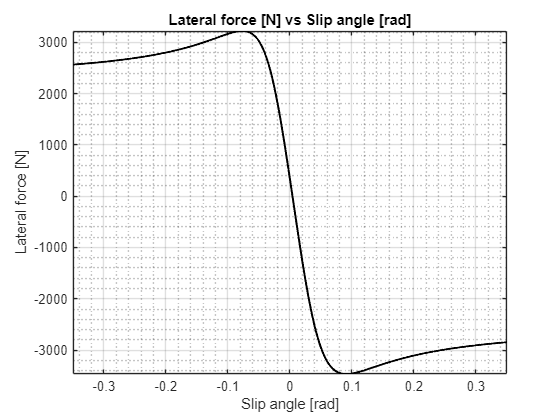

grid on
grid minor
legend off

Get tire specification from plot. プロットよりタイヤ特性を取得。

set(groot, "ShowHiddenHandles", "on");
h = findobj(f1.Children, "Type", "Axes");
l = findobj(h.Children, "HandleVisibility", "off");
x = l.XData';
y = l.YData';

## Linear regression at slip angles 0°~1°.

## スリップ角０°~１°での線形回帰

Calculation of linear regression. 線形回帰の計算

ind = (abs(x) <= pi/180);
fitobject = fit(x(ind), y(ind), "poly1");
cp = abs(fitobject.p1);
os = fitobject.p2;
disp(['Front tire corner stiffness (N/rad) : ', num2str(cp, '%.0f')])

Front tire corner stiffness (N/rad) : 79085


plot for validation. 確認用のグラフプロット

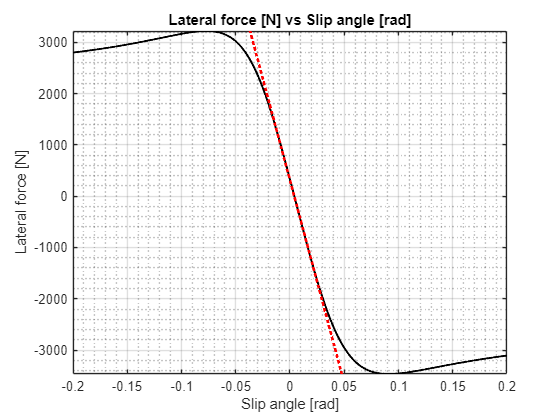

f2 = figure;
tm2 = plot(obj, Parent=f2, Direction="alpha", Magnitude=0.2, Fz=fz*9.81);
xrng = tm2.XLim;
yrng = tm2.YLim;
hold on
plot(x, -cp*x+os, "r:", LineWidth=2);
xlim(xrng);
ylim(yrng);
hold off
grid on
grid minor
legend off

poseprocessing. 終了処理

set(groot, "ShowHiddenHandles", "off");